clear; clc; close all;

% Define variables
    conditions = [1.7, 16764]; % Each row: [M0, H (m)]5, 24384;
    M0 = conditions(1, 1); H = conditions(1, 2);
    [T0, a0, P0, rho0] = atmosisa(H);
    M0_sls = 0; T0_sls = 288.15; P0_sls = 101325;

Gh = 4/3; Gc = 7/5; R = 287; beta = 0.25; % beta = m_F / mc
bl = 0; % Percentage of the bleed air, m_bl / m_core
m0_sls = 275; % unit: kg/s
    To0_sls = T0_sls * (1 + (Gc-1)/2 * M0_sls^2);
    Po0_sls = P0_sls * (1 + (Gc-1)/2 * M0_sls^2)^(Gc/(Gc-1));
    To0 = T0 * (1 + (Gc-1)/2 * M0^2);
    Po0 = P0 * (1 + (Gc-1)/2 * M0^2)^(Gc/(Gc-1));
    m0_c = m0_sls * (sqrt(To0_sls/288.15) / (Po0_sls/101325)); % corrected mass flow rate
    m0_fl = m0_c / (sqrt(To0/288.15) / (Po0/101325)); % mass flow rate at the flight condition

M3 = 0.3; % Assume the inlet Mach number
To3 = 948.59; % Initial temperature in K
Po3 = 1.1242e6; % Initial pressure in Pa
m3 = m0_fl * (1/ (1+beta)); % Core flow at station 3
m31 = m3 * (1-bl); % Core flow at station 31

D3 = M3/ ( 1 + (Gc-1)/2 * M3^2 )^ ( (Gc+1)/2/(Gc-1) );
A3 = m31 *sqrt(To3*R/Gc) / Po3 / D3; % unit: m^2

To4 = [1200, 1400, 1600, 1800, 2000]; % Turbine inlet temperatures in K
N = 10; % Number of control volumes dividing the combustor

% Create a figure for plotting
figure;
hold on;
grid on;

title('Mach Number and Area Distribution Along Axis', 'FontSize', 16);

% Colors for each To4 set
colors = lines(length(To4));

% Preallocate arrays
To = zeros(N+1, 1); M = zeros(N+1, 1); A = zeros(N+1, 1); Po = zeros(N+1, 1);
To(1) = To3; M(1) = M3; Po(1) = Po3; A(1) = 1; %A3; % Set inlet conditions

% Loop over different To4 values
for j = 1:length(To4)

    % Calculate temperature difference for each cell
    TD = (To4(j) - To3) / (N-1);

    for n = 2:N+1
        To(n) = TD + To(n-1);
        TR = To(n) / To(n-1);        
        M(n) = sqrt(M(n-1)^2 / (TR + (Gh-1)/2 * M(n-1)^2 * (TR-1))); % M at the outlet of cell n
        
        PoR(n-1) = ( (1 + (Gh-1)/2 * M(n)^2)/(1 + (Gh-1)/2 * M(n-1)^2) )^ (Gh / (Gh-1));
        Po(n) = PoR(n-1) * Po(n-1);
        A(n) = A(n-1) * (M(n-1) / M(n))^2;  % Example calculation for area ratio
        AR(n-1) = A(n) / A(n-1);
    end
    
    % Create a table
    resultsTable = table((1:N+1)', M, Po, A, [PoR'; NaN], [AR'; NaN], 'VariableNames', {'Cell', 'M', 'Po', 'A', 'PoR', 'AR'});
       
    % Calculate the Total Pressure Loss
    PL(j) = max(Po) - min (Po);
    fprintf('For To4 = %d K, the total pressure loss throughout the combustor is %.4e Pa\n', To4(j), PL(j));

    disp(resultsTable); % Display the table
    
    % Plot Mach number on the left y-axis
    yyaxis left;
    plot(1:N+1, M, 'Linestyle', '--', 'Marker', 'none', 'LineWidth', 2, 'DisplayName', sprintf('M for To4 = %d K', To4(j)), 'Color', colors(j,:));
    ylabel('Mach Number', 'FontSize', 14);

    % Plot Area on the right y-axis
    yyaxis right;
    plot(1:N+1, A, 'LineStyle', '-', 'Marker', '*', 'LineWidth', 2, 'DisplayName', sprintf('A for To4 = %d K', To4(j)), 'Color', colors(j,:));
    ylabel('A(x)/A_{3}', 'FontSize', 14);
    xlim([1 N+1]);
end

For To4 = 1200 K, the total pressure loss throughout the combustor is 1.5215e+04 Pa


    Cell       M           Po          A         PoR        AR  
    ____    _______    __________    ______    _______    ______

      1         0.3    1.1242e+06         1    0.99829    1.0299
      2     0.29561    1.1223e+06    1.0299    0.99838     1.029
      3     0.29142    1.1205e+06    1.0598    0.99847    1.0282
      4     0.28739    1.1187e+06    1.0897    0.99855    1.0274
      5     0.28353    1.1171e+06    1.1196    0.99863    1.0267
      6     0.27982    1.1156e+06    1.1495    0.99869     1.026
      7     0.27625    1.1141e+06    1.1793    0.99876    1.0253
      8     0.27281    1.1127e+06    1.2092    0.99882    1.0247
      9      0.2695    1.1114e+06    1.2391    0.99887    1.0241
     10     0.26631    1.1102e+06     1.269    0.99893    1.0236
     11     0.2

For To4 = 1400 K, the total pressure loss throughout the combustor is 2.3030e+04 Pa


    Cell       M           Po          A         PoR        AR  
    ____    _______    __________    ______    _______    ______

      1         0.3    1.1242e+06         1    0.99699    1.0537
      2     0.29226    1.1208e+06    1.0537    0.99728    1.0509
      3     0.28509    1.1178e+06    1.1073    0.99753    1.0485
      4     0.27842     1.115e+06     1.161    0.99775    1.0462
      5      0.2722    1.1125e+06    1.2147    0.99794    1.0442
      6     0.26638    1.1102e+06    1.2683     0.9981    1.0423
      7     0.26092    1.1081e+06     1.322    0.99825    1.0406
      8     0.25578    1.1062e+06    1.3757    0.99838     1.039
      9     0.25093    1.1044e+06    1.4293     0.9985    1.0375
     10     0.24635    1.1027e+06     1.483     0.9986    1.0362
     11     0.2

For To4 = 1600 K, the total pressure loss throughout the combustor is 2.8725e+04 Pa


    Cell       M           Po          A         PoR        AR  
    ____    _______    __________    ______    _______    ______

      1         0.3    1.1242e+06         1    0.99576    1.0774
      2     0.28902    1.1194e+06    1.0774    0.99632    1.0719
      3     0.27916    1.1153e+06    1.1549    0.99678    1.0671
      4     0.27024    1.1117e+06    1.2323    0.99716    1.0628
      5     0.26213    1.1086e+06    1.3098    0.99747    1.0591
      6     0.25471    1.1058e+06    1.3872    0.99774    1.0558
      7     0.24789    1.1033e+06    1.4647    0.99797    1.0529
      8     0.24158     1.101e+06    1.5421    0.99816    1.0502
      9     0.23573     1.099e+06    1.6196    0.99833    1.0478
     10     0.23029    1.0972e+06     1.697    0.99847    1.0456
     11     0.2

For To4 = 1800 K, the total pressure loss throughout the combustor is 3.3059e+04 Pa


    Cell       M           Po          A         PoR        AR  
    ____    _______    __________    ______    _______    ______

      1         0.3    1.1242e+06         1    0.99458    1.1012
      2     0.28588    1.1181e+06    1.1012    0.99548    1.0919
      3     0.27358    1.1131e+06    1.2024    0.99618    1.0842
      4     0.26275    1.1088e+06    1.3037    0.99673    1.0776
      5      0.2531    1.1052e+06    1.4049    0.99716    1.0721
      6     0.24445     1.102e+06    1.5061    0.99752    1.0672
      7     0.23663    1.0993e+06    1.6073    0.99781     1.063
      8     0.22951    1.0969e+06    1.7086    0.99805    1.0592
      9       0.223    1.0948e+06    1.8098    0.99826    1.0559
     10     0.21701    1.0929e+06     1.911    0.99843     1.053
     11     0.2

For To4 = 2000 K, the total pressure loss throughout the combustor is 3.6468e+04 Pa


    Cell       M           Po          A        PoR        AR  
    ____    _______    __________    _____    _______    ______

      1         0.3    1.1242e+06        1    0.99345     1.125
      2     0.28284    1.1168e+06    1.125    0.99475    1.1111
      3     0.26833     1.111e+06     1.25     0.9957       1.1
      4     0.25584    1.1062e+06    1.375    0.99641    1.0909
      5     0.24495    1.1022e+06      1.5    0.99696    1.0833
      6     0.23534    1.0989e+06    1.625    0.99739    1.0769
      7     0.22678     1.096e+06     1.75    0.99774    1.0714
      8     0.21909    1.0935e+06    1.875    0.99802    1.0667
      9     0.21213    1.0913e+06        2    0.99825    1.0625
     10      0.2058    1.0894e+06    2.125    0.99844    1.0588
     11         0.2    1.08

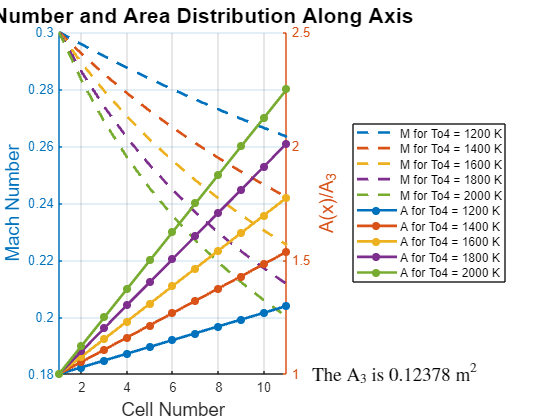


% Configure axis and legend
xlabel('Cell Number', 'FontSize', 14);
legend('show', 'Location', 'eastoutside'); 
text(5, M(11), ['The A$_{3}$ is ', num2str(A3),' m$^2$'], 'Interpreter', 'latex', 'FontSize', 14,'Position',[12,1]);
hold off;

**Fuel Mass Flow Rate & Emissions**

Tb = 573.15; % the boiling point Tb, unit: K
Hv = 3.6e5; % the latent heat of evaporation
Tfi = [300, 400, 500, 588.706]; % Initial fuel temperature, unit: K 
Eb = 0.98; dHB = 4.3e7; % unit: J/kg

% Initialize the results table with cell arrays to handle different data types
results = []; results_EI = []; results_g = [];

% Initialize arrays for Plot 2
emissions = cell(length(To4), 3); % Each cell will hold a matrix for CO, UHC, NOx

for i = 1:length(To4)
    for j = 1:length(Tfi)
        [Cpfi, ~] = CP_f(Tfi(j), false); [Cpf4, ~] = CP_f(To4(i), false); % Cp for the fuel
        [~, Cpa3] = CP_f(To3, false); [~, Cpa4] = CP_f(To4(i), false); % Cp for the air
        
        CA = Cpfi*Tfi(j) + Cpf4*To4(i) - Eb*dHB;
        CB = -Cpfi*Tfi(j) + Cpa4*To4(i) + Hv - Cpa3*To3 -Cpf4*To4(i) - Eb*dHB;
        CC = -Cpa3*To3 + Cpa4*To4(i); 
        f_roots = roots([CA, CB, CC]);        
        positive_f = f_roots(f_roots > 0); % Select positive root
        f_v(i,j) = positive_f;

        Gc = 7/5; Gh = 4/3; Cpc = Gc * R / (Gc - 1); Cph = Gh * R / (Gh - 1);
        fb = (Cph*To4(i) - Cpc*To3) / (Eb*dHB - Cph*To4(i)); % when f << 1;
        f_v2(i,j) = fb;

        mf = m31 * positive_f;
        mf_ideal = m31 * fb;
        
        % Store results
        results = [results; table(To4(i), Tfi(j), positive_f, fb, mf, mf_ideal, 'VariableNames', {'To4', 'Tfi', 'f1', 'f2', 'mf1 (kg/s)', 'mf2 (kg/s)'})];
        %% Calculate emission indices
        [EI_CO, EI_UHC] = UHC_CO(Eb*100); 
        war = 0.7;  % Assume the humidity is 70%
        EI_NOx = calculate_EI_NOx(Po3, To3, war);
        emissions{i} = [emissions{i}; [EI_CO * mf, EI_UHC * mf, EI_NOx * mf]];
        % CO(j) = EI_CO * mf;
        % UHC(j) = EI_UHC * mf;
        % NOx(j) = EI_NOx * mf;
    
        % Append results for the current iteration
        results_EI = [results_EI; table(To4(i), EI_CO, EI_UHC, EI_NOx, 'VariableNames', {'To4', 'EI_CO (g/kg fuel)', 'EI_UHC (g/kg fuel)', 'EI_NOx (g/kg fuel)'})];
        results_g = [results_g; table(To4(i), Tfi(j), EI_CO*mf, EI_UHC*mf, EI_NOx*mf, 'VariableNames', {'To4', 'Tfi', 'CO (g)', 'UHC (g)', 'NOx (g)'})];
    end
end

% Plot 1: Fuel Air Ratio vs. Initial Fuel Temperature
% Create figure for plotting
figure;
hold on;
grid on;
colors = lines(length(To4)); % Generate distinct colors for each To4 value
for i = 1:length(To4)
    plot(Tfi, f_v(i,:), 'LineWidth', 2, 'Color', colors(i, :), 'DisplayName', sprintf('f1, To4 = %d K', To4(i)));
    plot(Tfi, f_v2(i,:), 'Linestyle', '--', 'Color', colors(i, :), 'DisplayName', sprintf('f2, To4 = %d K', To4(i)));
end
xlabel('Initial Fuel Temperature T_{fi} (K)', 'FontSize', 14);
ylabel('Fuel Air Ratio, f', 'FontSize', 14);
title('Fuel Air Ratio vs. Initial Fuel Temperature for Various To4', 'FontSize', 14);
legend('show');
hold off;

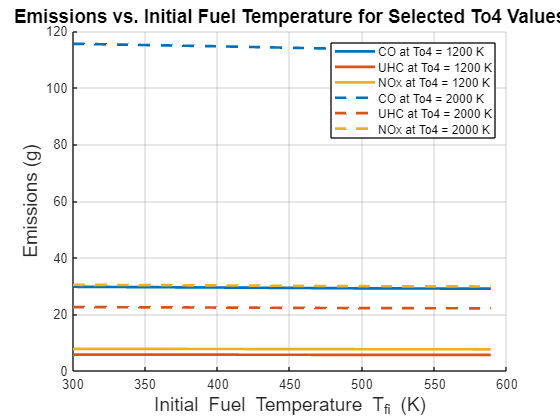


% Plot 2: Emissions vs. Initial Fuel Temperature for selected To4 = 1200 K and 2000 K
figure;
hold on;
grid on;
lineStyles = {'-', '--'}; % Dashed for 2000, solid for 1200
colors = lines(3); % Colors for CO, UHC, NOx
selectedIndices = [find(To4 == 1200), find(To4 == 2000)]; % Indices of To4 = 1200 and 2000
% Define labels for emissions
emissionLabels = {'CO', 'UHC', 'NOx'};
for idx = 1:length(selectedIndices)
    i = selectedIndices(idx);
    emissions_matrix = emissions{i}; % Assuming each row in emissions_matrix corresponds to Tfi
    for k = 1:3 % Loop through emissions types
        plot(Tfi, emissions_matrix(:, k), 'Color', colors(k, :), 'LineWidth', 2, 'LineStyle', lineStyles{idx}, ...
             'DisplayName', sprintf('%s at To4 = %d K', emissionLabels{k}, To4(i)));
    end
end
xlabel('Initial Fuel Temperature T_{fi} (K)', 'FontSize', 14);
ylabel('Emissions (g)', 'FontSize', 14);
title('Emissions vs. Initial Fuel Temperature for Selected To4 Values', 'FontSize', 14);
legend('show');
hold off;


% Display results
disp(results);

    To4      Tfi         f1           f2       mf1 (kg/s)    mf2 (kg/s)
    ____    ______    _________    ________    __________    __________

    1200       300    0.0070798     0.01042     0.63528       0.93499  
    1200       400    0.0070181     0.01042     0.62975       0.93499  
    1200       500    0.0069476     0.01042     0.62342       0.93499  
    1200    588.71    0.0069202     0.01042     0.62096       0.93499  
    1400       300     0.012483    0.016144      1.1201        1.4486  
    1400       400     0.012377    0.016144      1.1106        1.4486  
    1400       500     0.012257    0.016144      1.0998        1.4486  
    1400    588.71      0.01221    0.016144      1.0956        1.4486  
    1600       300     0.017679    0.021932      1.5864         1.968  
   

disp(results_EI);

    To4     EI_CO (g/kg fuel)    EI_UHC (g/kg fuel)    EI_NOx (g/kg fuel)
    ____    _________________    __________________    __________________

    1200         46.795                9.1436                12.332      
    1200         46.795                9.1436                12.332      
    1200         46.795                9.1436                12.332      
    1200         46.795                9.1436                12.332      
    1400         46.795                9.1436                12.332      
    1400         46.795                9.1436                12.332      
    1400         46.795                9.1436                12.332      
    1400         46.795                9.1436                12.332      
    1600         46.795                9.1436                12.332      
    1600         46.795                9.1436    

disp(results_g);

    To4      Tfi      CO (g)    UHC (g)    NOx (g)
    ____    ______    ______    _______    _______

    1200       300    29.728    5.8088      7.834 
    1200       400    29.469    5.7582     7.7658 
    1200       500    29.173    5.7003     7.6877 
    1200    588.71    29.058    5.6778     7.6574 
    1400       300    52.414    10.242     13.813 
    1400       400    51.972    10.155     13.696 
    1400       500    51.466    10.056     13.562 
    1400    588.71    51.269    10.018     13.511 
    1600       300    74.233    14.505     19.562 
    1600       400    73.625    14.386     19.402 
    1600       500    72.929     14.25     19.219 
    1600    588.71    72.659    14.197     19.147 
    1800       300     95.24     18.61     25.098 
    1800       400    94.482    18.462     24.898 
    1800     

**Cp curve fitting**

function [CPJA_v, CPa_v] = CP_f(Tin, showPlot)
    % returns specific heat values for Jet-A vapor, Jet-A liquid, and air
    % INPUTS-showPlot: Boolean flag to indicate whether to show plots (true/false)
   
    % Load data
    data = readtable('C:\Users\SJ Chen\OneDrive - purdue.edu\Purdue\2024Fall\AAE538 Air-Breathing Propulsion\Project\Specificheat.csv'); 

    T = data.T;          % Temperature in K
    CPJAg = data.CPJAg;  % Specific heat of Jet-A vapor in J/kg/K
    CPJAL = data.CPJAL;  % Specific heat of Jet-A liquid in J/kg/K
    CPa = data.CPa;      % Specific heat of air in J/kg/K

    % Create spline representations of the variables
    CPJAg_spline = spline(T, CPJAg);
    CPJAL_spline = spline(T(~isnan(CPJAL)), CPJAL(~isnan(CPJAL)));  % Use only non-NaN entries
    CPa_spline = spline(T, CPa);

    % Check if input temperature is within the range of the data
    if Tin < min(T) || Tin > max(T)
        error('Input temperature is out of range of the available data.');
    end

    % Evaluate specific heat for air at the input temperature
    CPa_v = ppval(CPa_spline, Tin);

    % Determine specific heat for Jet-A (liquid or vapor depending on temperature)
    if Tin <= max(T(~isnan(CPJAL)))
        % If the temperature is within the range of Jet-A liquid, use CPJAL
        CPJA_v = ppval(CPJAL_spline, Tin);
    else
        % Otherwise, use Jet-A vapor specific heat
        CPJA_v = ppval(CPJAg_spline, Tin);
    end

    % Plotting if showPlot is true
    if showPlot
        % Define a finer temperature range for plotting the splines
        T_fine = linspace(min(T), max(T), 300);
        T_fine_JL = linspace(min(T(~isnan(CPJAL))), max(T(~isnan(CPJAL))), 300);  % Only within the valid range of CPJAL

        % Evaluate splines on the finer temperature grid
        CPJAg_fine = ppval(CPJAg_spline, T_fine);
        CPJAL_fine = ppval(CPJAL_spline, T_fine_JL);
        CPa_fine = ppval(CPa_spline, T_fine);

        % Plotting
        figure;

        % Specific heat of Jet-A vapor
        subplot(3,1,1); 
        plot(T, CPJAg, 'o', T_fine, CPJAg_fine, '-'); 
        title('Specific Heat Capacity of Jet-A Vapor'); 
        xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

        % Specific heat of Jet-A liquid
        subplot(3,1,2); 
        plot(T(~isnan(CPJAL)), CPJAL(~isnan(CPJAL)), 'o', T_fine_JL, CPJAL_fine, '-'); 
        title('Specific Heat Capacity of Jet-A Liquid'); 
        xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

        % Specific heat of air
        subplot(3,1,3); 
        plot(T, CPa, 'o', T_fine, CPa_fine, '-'); 
        title('Specific Heat Capacity of Air'); 
        xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');
    end
end

**Emission**

function [EI_CO, EI_UHC] = UHC_CO(efficiency)
    % Constants
    C1 = 3.15; C2 = -4.3;

    % Equation setup
    fun = @(EI_CO) 0.1 * (0.232*EI_CO + 10^(C1 * log10(EI_CO) + C2)) - (100 - efficiency);

    % Initial guess
    EI_CO_guess = 10;  % Adjust as needed based on expected range of EI_CO

    % Solve using fsolve
    options = optimoptions('fsolve', 'Display', 'none'); % Hide iteration process
    EI_CO = fsolve(fun, EI_CO_guess, options);

    % Calculate EI_UHC based on EI_CO
    EI_UHC = 10^(C1 * log10(EI_CO) + C2);
    
    return
end

function EI_NOx = calculate_EI_NOx(Po3, To3, war)
  
    % Calculate S_NOx using the given formula
    S_NOx = (Po3 / 2965e3)^0.4 * exp((To3 - 826) / 194 + (6.29 - 100 * war) / 53.2);

    % Calculate EI for NOx using the linear relationship
    EI_NOx = 32 * S_NOx;
    
    return
end
